# Ejemplo 4: calcular el volumen entre dos superficies

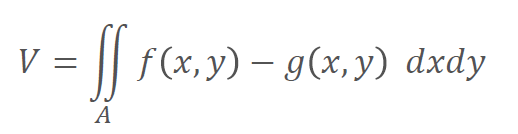

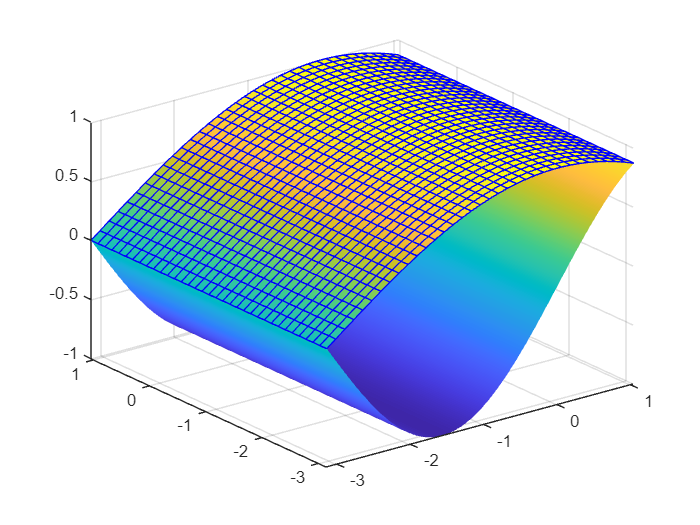

clear all
close all

a=-pi;
b=pi/3;

f=@(x,y) cos(x/2);
g=@(x,y) sin(x);
fsurf(f,[a b a b],'EdgeColor','b'); hold on
fsurf(g,[a b a b],'EdgeColor','none'); 

% el volumen real lo podemos calcular como (b-a)integral(f(x)-g(x),a,b)
fg = @(x) cos(x/2)-sin(x);

V_real = (b-a)*integral(fg,a,b)

V_real = 18.8496

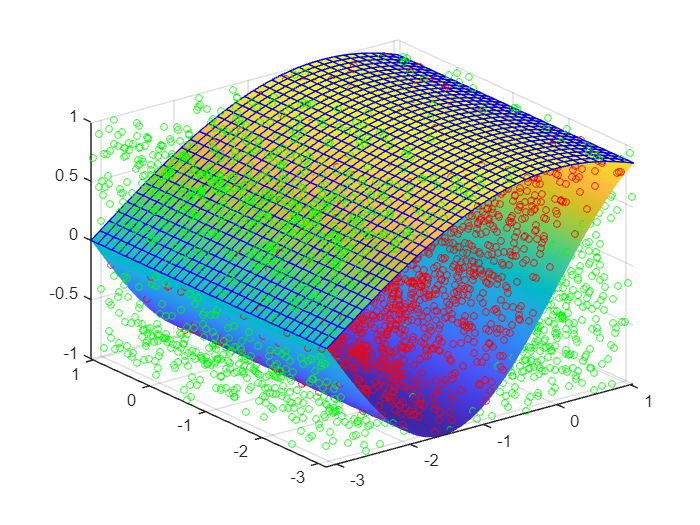

% El volumen entre las 2 superficies se encuentra dentro
% del hiperpoliedro [-pi,pi/3]x[-pi,pi/3]x[-1,1]
a=-pi;      b=pi/3;         h=[-1,1];

% Definimos el volumen del hiperpoliedro R
R=(b-a)*(b-a)*diff(h);

% Iniciar el experimento de Monte Carlo
nc=0;               % aciertos
n=5000;             % numero de intentos

% generar n números aleatorios uniformes entre 0 y 1 
r=rand(n,3);

% generamos una nube de n puntos en R [a,b]x[c,d]xh
% los puntos siguen una distribución uniforme en los intervalos
% [a,b], [c,d] y [0,h], donde h es una cota superior de f
x=a+r(:,1)*(b-a);         y=a+r(:,2)*(b-a);         z=h(1)+r(:,3)*diff(h);

% localizar los puntos que se encuentran entre las superficies f y g
cond1 = z<f(x,y);
cond2 = z>g(x,y);
idx = and(cond1,cond2); %(z<G(x)) &&  (z>F(x));

%--------------Contar el número de éxitos
nc=sum(idx);
vol_esti=R*nc/n;

%--------------Dibujar los resultados
plot3(x(idx,1),y(idx,1),z(idx,1),'ro','MarkerSize',4) % The points satisfying the criterion
plot3(x(~idx,1),y(~idx,1),z(~idx,1),'go','MarkerSize',4) % The points that not satify the criterion